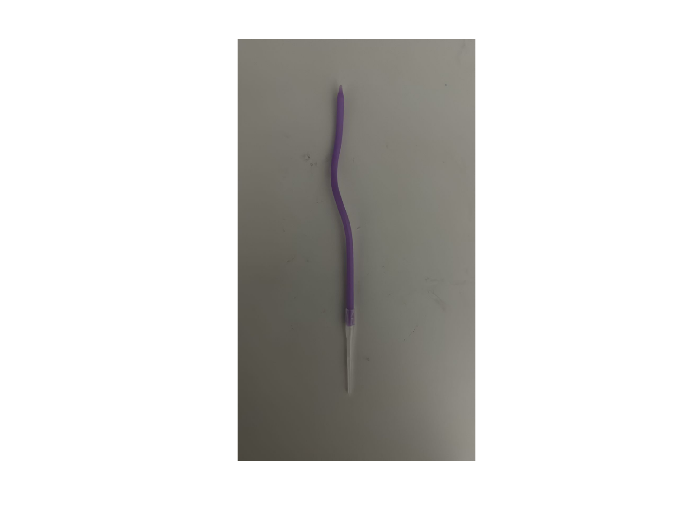

unzip('datasets.zip');
imds = imageDatastore('datasets','IncludeSubfolders',true,'LabelSource','foldernames');
tbl = countEachLabel(imds);

figure
montage(imds.Files(1:16:end))


[trainingSet, validationSet] = splitEachLabel(imds, 0.6, 'randomize');
bag = bagOfFeatures(trainingSet);

Creating Bag-Of-Features.
-------------------------
* Image category 1: candle
* Image category 2: fork
* Image category 3: knife
* Image category 4: marker
* Image category 5: spoon
* Selecting feature point locations using the Grid method.
* Extracting SURF features from the selected feature point locations.
** The GridStep is [8 8] and the BlockWidth is [32 64 96 128].

* Extracting features from 5 images...done. Extracted 481600 features.

* Keeping 80 percent of the strongest features from each category.

* Balancing the number of features across all image categories to improve clustering.
** Image category 1 has the least number of strongest features: 72320.
** Using the strongest 72320 features from each of the other image categories.

* Creating a 500 word visual vocabulary.
* Number of levels: 1
* Branching factor: 500
* Number of clustering steps: 1

* [Step 1/1] Clustering vocabulary level 1.
* Number of features          : 361600
* Number of clusters          : 500
* Initia


img = readimage(imds, 1);
featureVector = encode(bag, img);

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


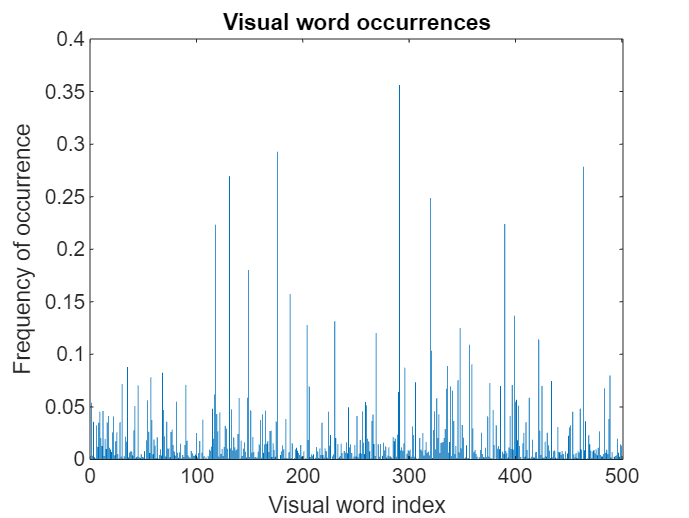


% Plot the histogram of visual word occurrences
figure
bar(featureVector)
title('Visual word occurrences')
xlabel('Visual word index')
ylabel('Frequency of occurrence')


categoryClassifier = trainImageCategoryClassifier(trainingSet, bag);

Training an image category classifier for 5 categories.
--------------------------------------------------------
* Category 1: candle
* Category 2: fork
* Category 3: knife
* Category 4: marker
* Category 5: spoon

* Encoding features for 5 images...done.

* Finished training the category classifier. Use evaluate to test the classifier on a test set.




confMatrix = evaluate(categoryClassifier, trainingSet);

Evaluating image category classifier for 5 categories.
-------------------------------------------------------

* Category 1: candle
* Category 2: fork
* Category 3: knife
* Category 4: marker
* Category 5: spoon

* Evaluating 5 images...done.

* Finished evaluating all the test sets.

* The confusion matrix for this test set is:


                           PREDICTED
KNOWN     | candle   fork   knife   marker   spoon   
-----------------------------------------------------
candle    | 1.00     0.00   0.00    0.00     0.00    
fork      | 0.00     1.00   0.00    0.00     0.00    
knife     | 0.00     0.00   1.00    0.00     0.00    
marker    | 0.00     0.00   0.00    1.00     0.00    
spoon     | 0.00     0.00   0.00    0.00     1.00    

* Average Accuracy is 1.00.



confMatrix = evaluate(categoryClassifier, validationSet);

Evaluating image category classifier for 5 categories.
-------------------------------------------------------

* Category 1: candle
* Category 2: fork
* Category 3: knife
* Category 4: marker
* Category 5: spoon

* Evaluating 5 images...done.

* Finished evaluating all the test sets.

* The confusion matrix for this test set is:


                           PREDICTED
KNOWN     | candle   fork   knife   marker   spoon   
-----------------------------------------------------
candle    | 1.00     0.00   0.00    0.00     0.00    
fork      | 0.00     0.00   0.00    0.00     1.00    
knife     | 0.00     0.00   1.00    0.00     0.00    
marker    | 0.00     0.00   0.00    1.00     0.00    
spoon     | 1.00     0.00   0.00    0.00     0.00    

* Average Accuracy is 0.60.



% Compute average accuracy
mean(diag(confMatrix))

ans = 0.6000

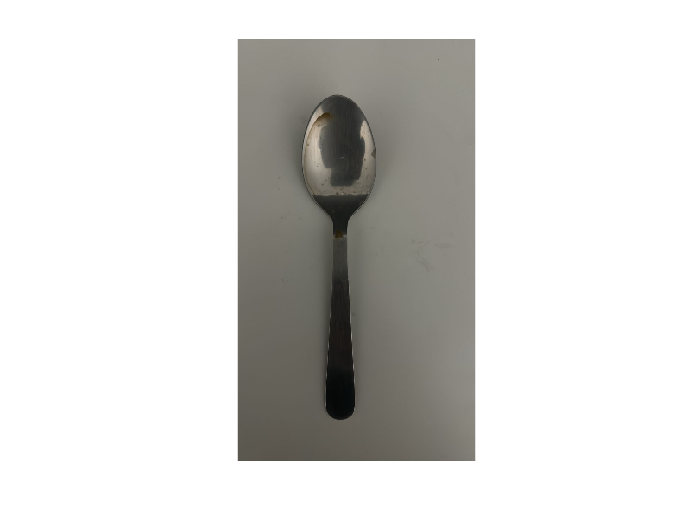


img = imread(fullfile('datasets','spoon','spoon-2.jpg'));
figure
imshow(img)

[labelIdx, scores] = predict(categoryClassifier, img);

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


% Display the string label
categoryClassifier.Labels(labelIdx)

ans = 1x1 cell array
    {'spoon'}
